# Analysis of the enerNoc dataset

## Dataset description

This is anonymized 5-minute energy usage data for 100 commercial/ industrial sites for 

2012. Actual reading values and identifying information such as geo coordinates and 

square footage have been anonymized, but the values have been skewed by a linear magnitude

so that comparisons over time and between sites will remain consistent.

## Metadata

The metadata contains each site ID including industry,  square footage, lat/lng and timezone. 

Note that because lat/lng are randomized by a  small amount, the exact location may not

appear correct (e.g. the point might be over  a body of water, etc.).

## Location

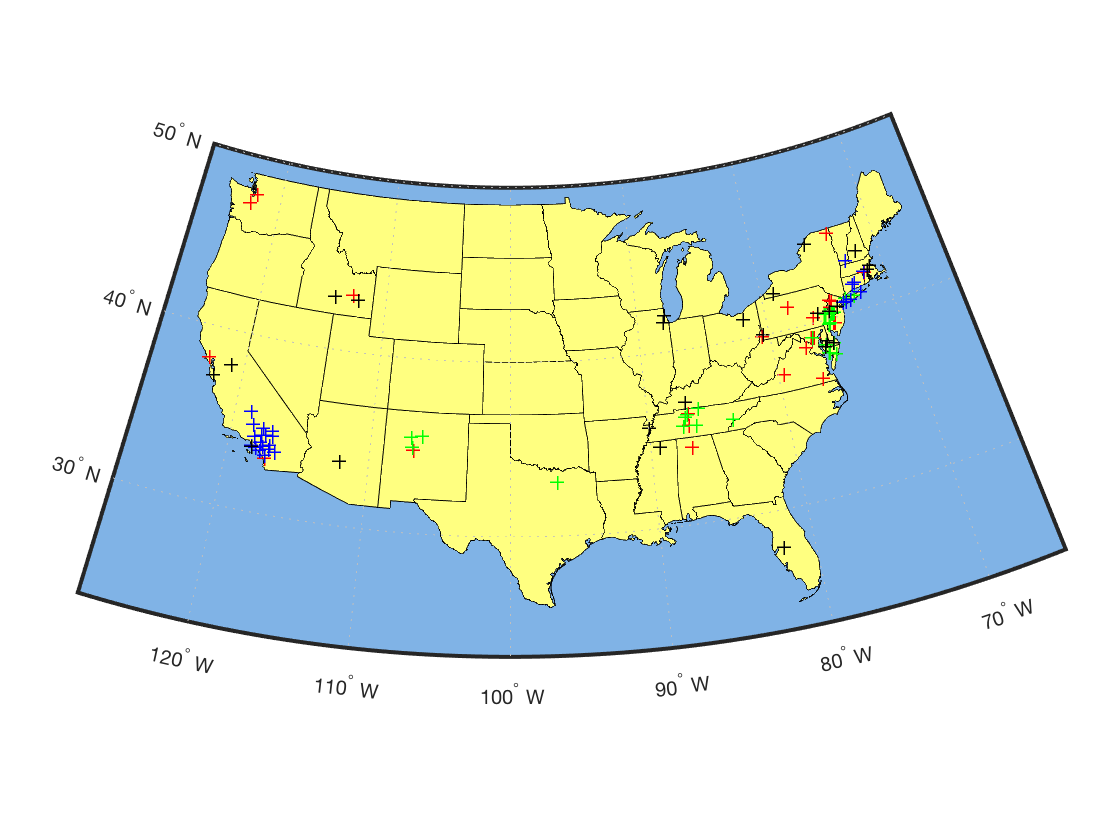

ReadAllMetadata

commercial = allsites(allsites.INDUSTRY == categorical("Commercial Property"),:);
education = allsites(allsites.INDUSTRY == categorical("Education"),:);
food = allsites(allsites.INDUSTRY == categorical("Food Sales & Storage"),:);
industrial = allsites(allsites.INDUSTRY == categorical("Light Industrial"),:);
states = geoshape(shaperead('usastatehi', 'UseGeoCoords', true));
figure
ax = usamap('conus');
oceanColor = [.5 .7 .9];
setm(ax, 'FFaceColor', oceanColor)
geoshow(states)

% Commercial
pts = [commercial.LAT'; commercial.LNG'];
p = geopoint;
p(1:length(pts)) = pts;

p.Metadata.FeatureType = 'waypoint';
p.Name = cellstr(string(commercial.SITE_ID));
p.Description = cellstr(string(commercial.SUB_INDUSTRY));

geoshow(p, 'DisplayType', 'point', 'MarkerEdgeColor', 'r')

% Education
pts = [education.LAT'; education.LNG'];
p = geopoint;
p(1:length(pts)) = pts;

p.Metadata.FeatureType = 'waypoint';
p.Name = cellstr(string(education.SITE_ID));
p.Description = cellstr(string(education.SUB_INDUSTRY));

geoshow(p, 'DisplayType', 'point', 'MarkerEdgeColor', 'g')

% Food
pts = [food.LAT'; food.LNG'];
p = geopoint;
p(1:length(pts)) = pts;

p.Metadata.FeatureType = 'waypoint';
p.Name = cellstr(string(food.SITE_ID));
p.Description = cellstr(string(food.SUB_INDUSTRY));

geoshow(p, 'DisplayType', 'point', 'MarkerEdgeColor', 'b')

% Industrial
pts = [industrial.LAT'; industrial.LNG'];
p = geopoint;
p(1:length(pts)) = pts;

p.Metadata.FeatureType = 'waypoint';
p.Name = cellstr(string(industrial.SITE_ID));
p.Description = cellstr(string(industrial.SUB_INDUSTRY));

geoshow(p, 'DisplayType', 'point', 'MarkerEdgeColor', 'black')

## Average consumption per Industry

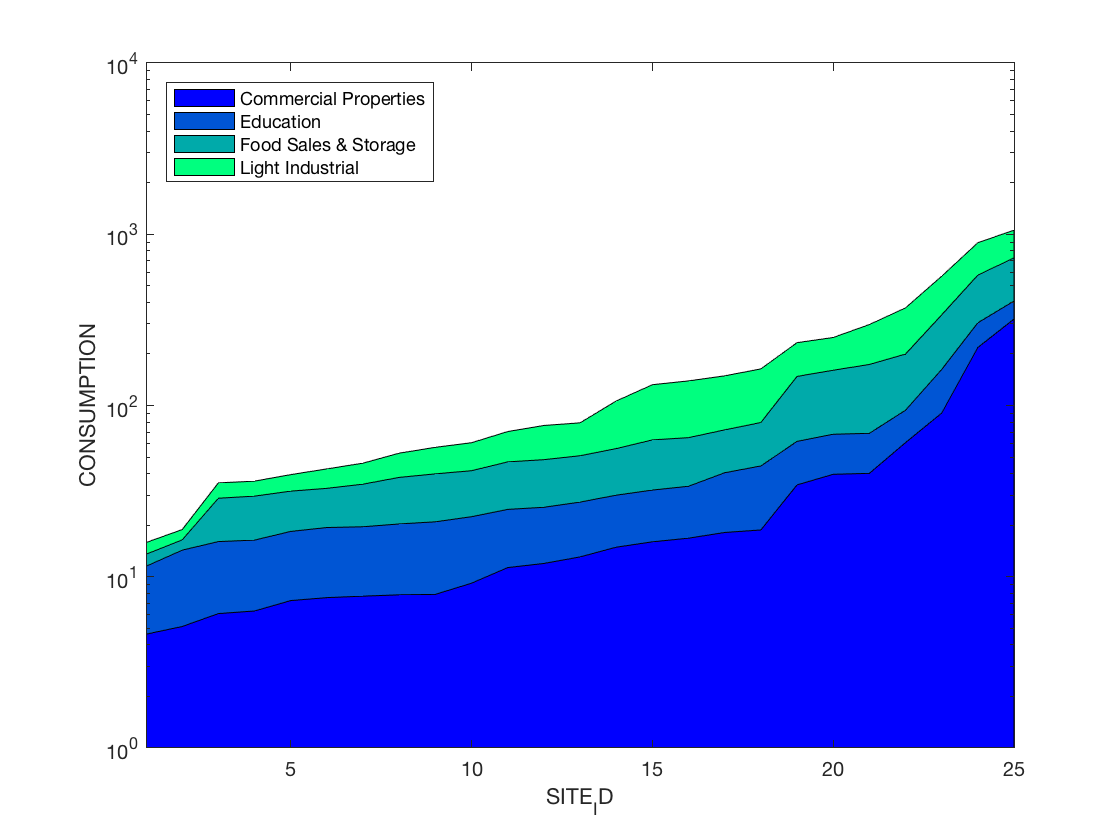

% Reading the data
tmp = dir('raw-data/*.csv');
fileList = string.empty(length(tmp),0);
for i = 1:length(tmp)
    fileList(i) = string(tmp(i).name);
end
clear tmp
load preprocessed-data/preprocessed.mat data;

meta = ReadMetadata('meta/all_sites_processed.csv');

commercialData = data(:,1:25);
educationData = data(:,26:50);
foodData = data(:,51:75);
industrialData = data(:,76:100);

sortedMeanCommercial = sort(mean(commercialData, 1))';
sortedMeanEducation = sort(mean(educationData, 1))';
sortedMeanFood = sort(mean(foodData, 1))';
sortedMeanIndustrial = sort(mean(industrialData, 1))';

figure;
area([sortedMeanCommercial, sortedMeanEducation, sortedMeanFood, sortedMeanIndustrial], ...
    'FaceColor','flat');
legend(["Commercial Properties","Education","Food Sales & Storage","Light Industrial"], 'Location', 'northwest');
colormap winter;
xlim([1, 25])
xlabel("SITE_ID")
ylabel("CONSUMPTION")
set(gca, 'YScale', 'log')

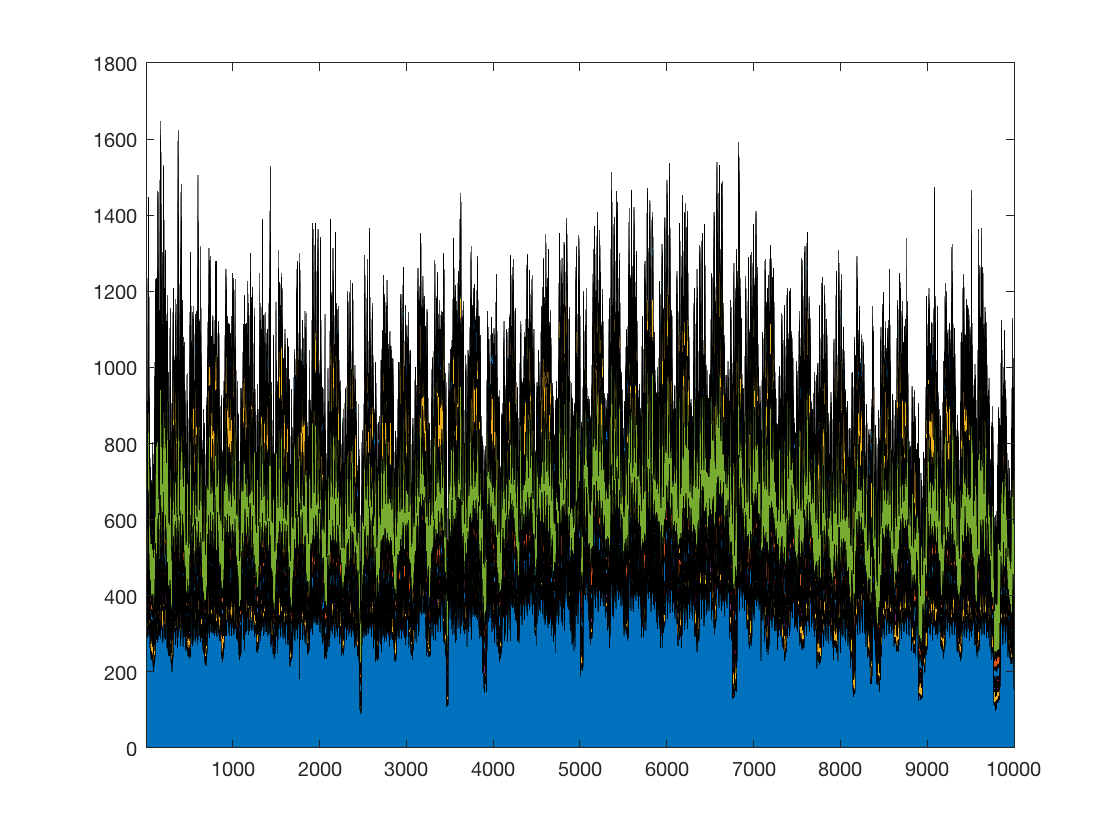

% commercialDataReduced = zeros([10000, 25], 'single');
% for i = 1:25
%     tmp = [(1:length(commercialData(:,i)))', commercialData(:,i)];
%     a = tsa.Array(tmp);
%     b = tsa.Dimensionality.visvalingam(a, 10000);
%     c = b.getData();
%     commercialDataReduced(:,i) = c(:,2);
% end
load preprocessed-data/splitedDataReduced.mat;
figure;
area(commercialDataReduced)
%legend(meta(1:25,1), 'Location', 'northwest');
xlim([1 length(commercialDataReduced)])

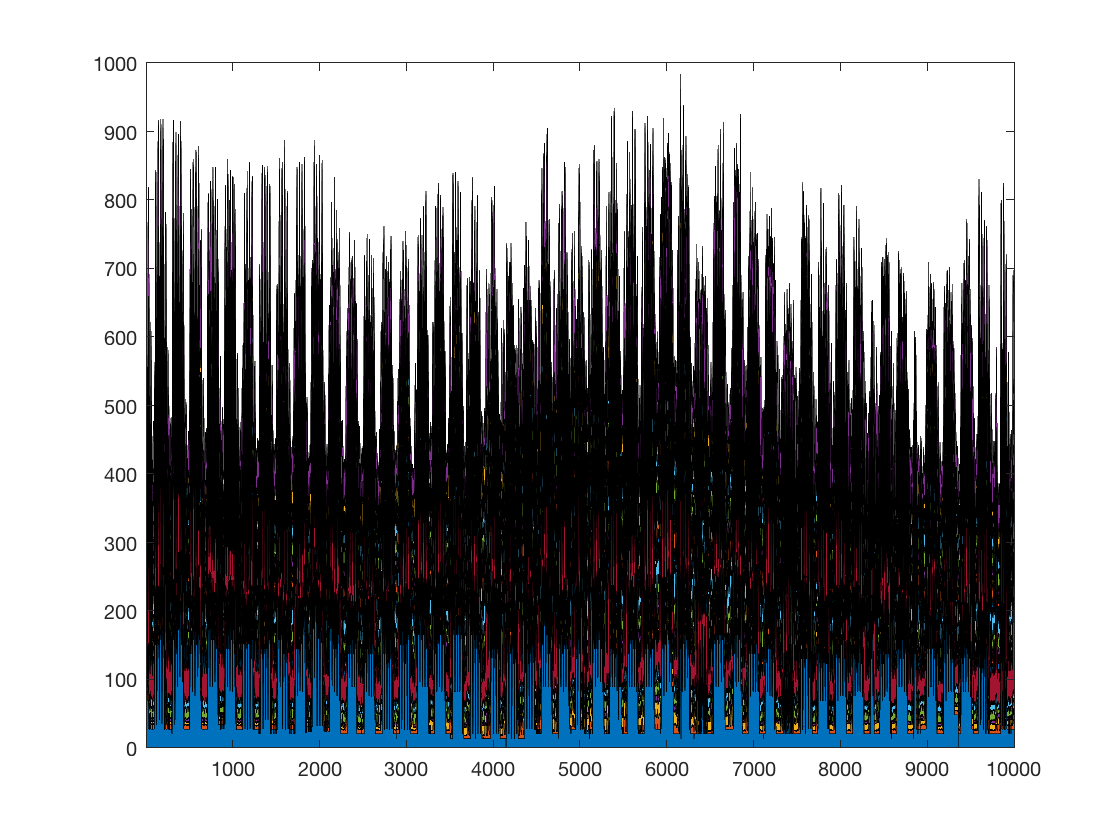

% educationDataReduced = zeros([10000, 25], 'single');
% for i = 1:25
%     tmp = [(1:length(educationData(:,i)))', educationData(:,i)];
%     a = tsa.Array(tmp);
%     b = tsa.Dimensionality.visvalingam(a, 10000);
%     c = b.getData();
%     educationDataReduced(:,i) = c(:,2);
% end

figure;
area(educationDataReduced)
%legend(meta(26:50,1), 'Location', 'northwest');
xlim([1 length(educationDataReduced)])

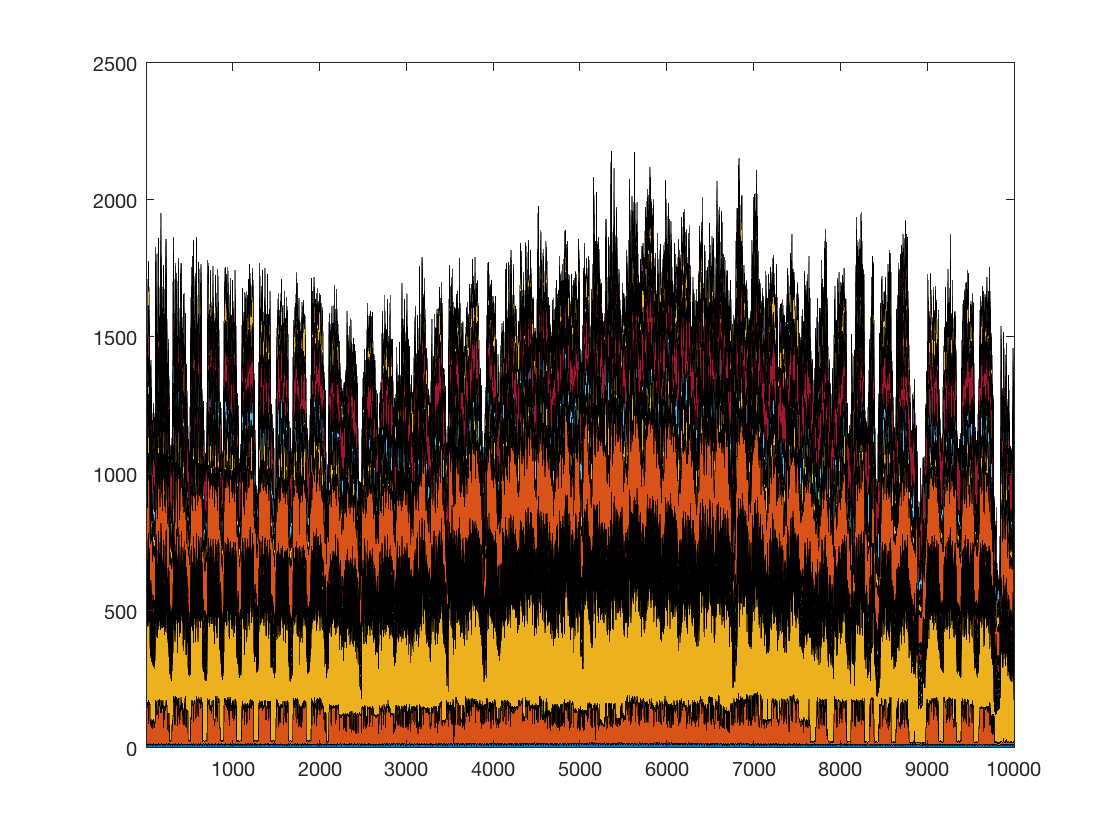

% foodDataReduced = zeros([10000, 25], 'single');
% for i = 1:25
%     tmp = [(1:length(foodData(:,i)))', foodData(:,i)];
%     a = tsa.Array(tmp);
%     b = tsa.Dimensionality.visvalingam(a, 10000);
%     c = b.getData();
%     foodDataReduced(:,i) = c(:,2);
% end

figure;
area(foodDataReduced)
%legend(meta(51:75,1), 'Location', 'northwest');
xlim([1 length(foodDataReduced)])

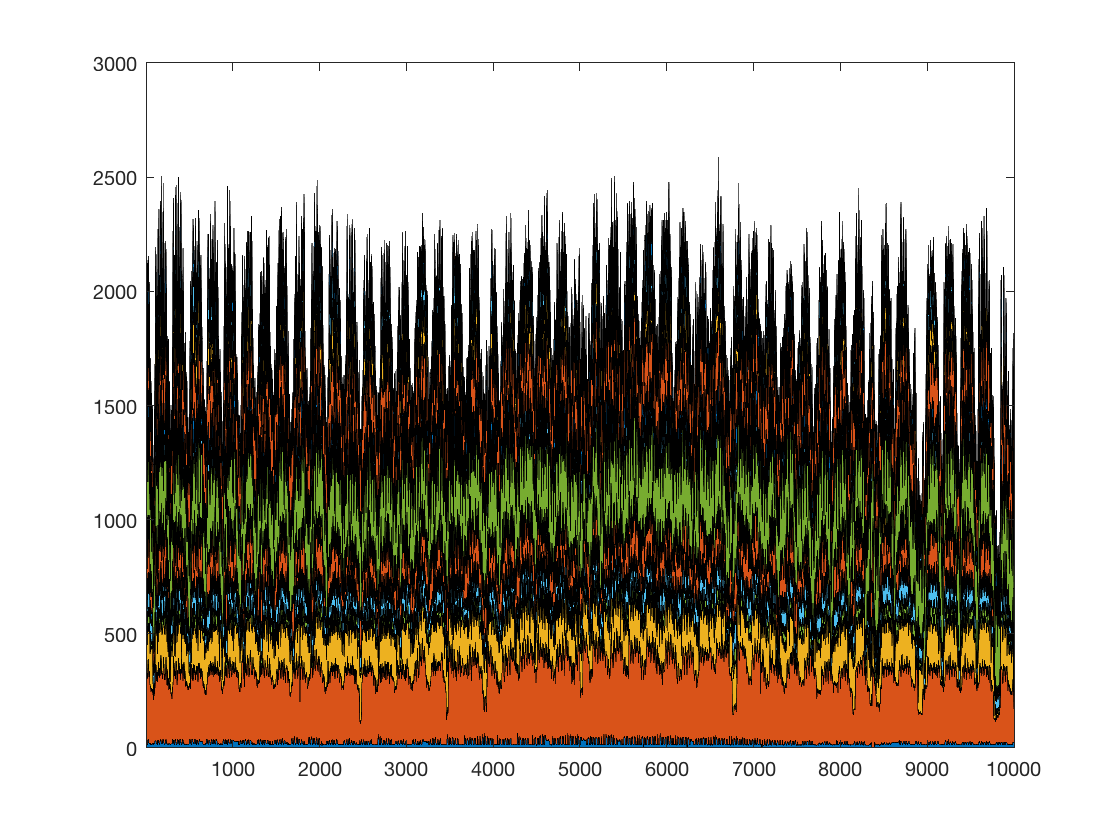

% industrialDataReduced = zeros([10000, 25], 'single');
% for i = 1:25
%     tmp = [(1:length(industrialData(:,i)))', industrialData(:,i)];
%     a = tsa.Array(tmp);
%     b = tsa.Dimensionality.visvalingam(a, 10000);
%     c = b.getData();
%     industrialDataReduced(:,i) = c(:,2);
% end

figure;
area(industrialDataReduced)
%legend(meta(76:100,1), 'Location', 'northwest');
xlim([1 length(industrialDataReduced)])

## Calculating the distance between the commercial properties

cdr = tsa.Array(commercialDataReduced);
cdrN = tsa.Normalization.maxMinNorm(cdr, 1.0, 0.0, 1e-8);
euclidean = tsa.Distances.euclidean(cdrN);
euclideanHost = euclidean.getData();
euclideanHost = euclideanHost + euclideanHost';

## Computing a dendrogram 

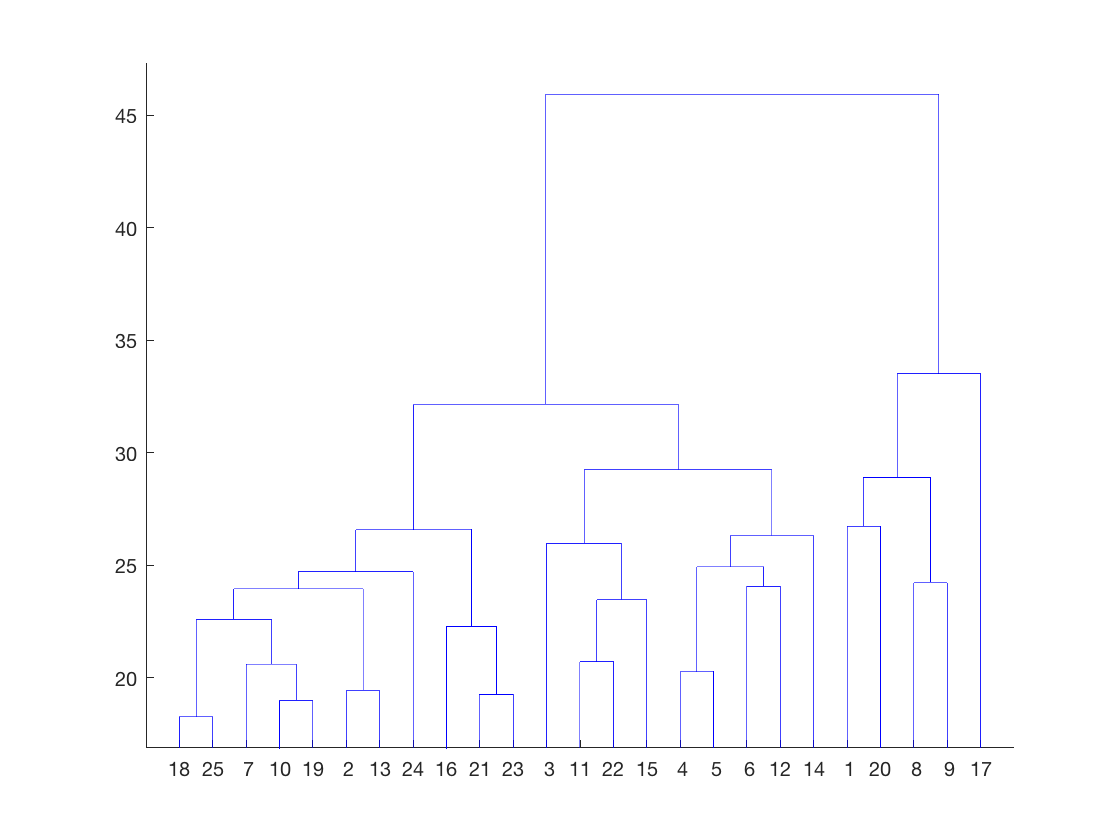

y = squareform(euclideanHost);
Z = linkage(y, 'complete');
figure
dendrogram(Z)

## Displaying a sorted heatmap

As it can be observed there are 2 groups in the commercial properties industry sites. The heatmap confirms what we observe in the data. The sites from 100 to 236 belong to the first group and the rest of the sites take part of the second group.

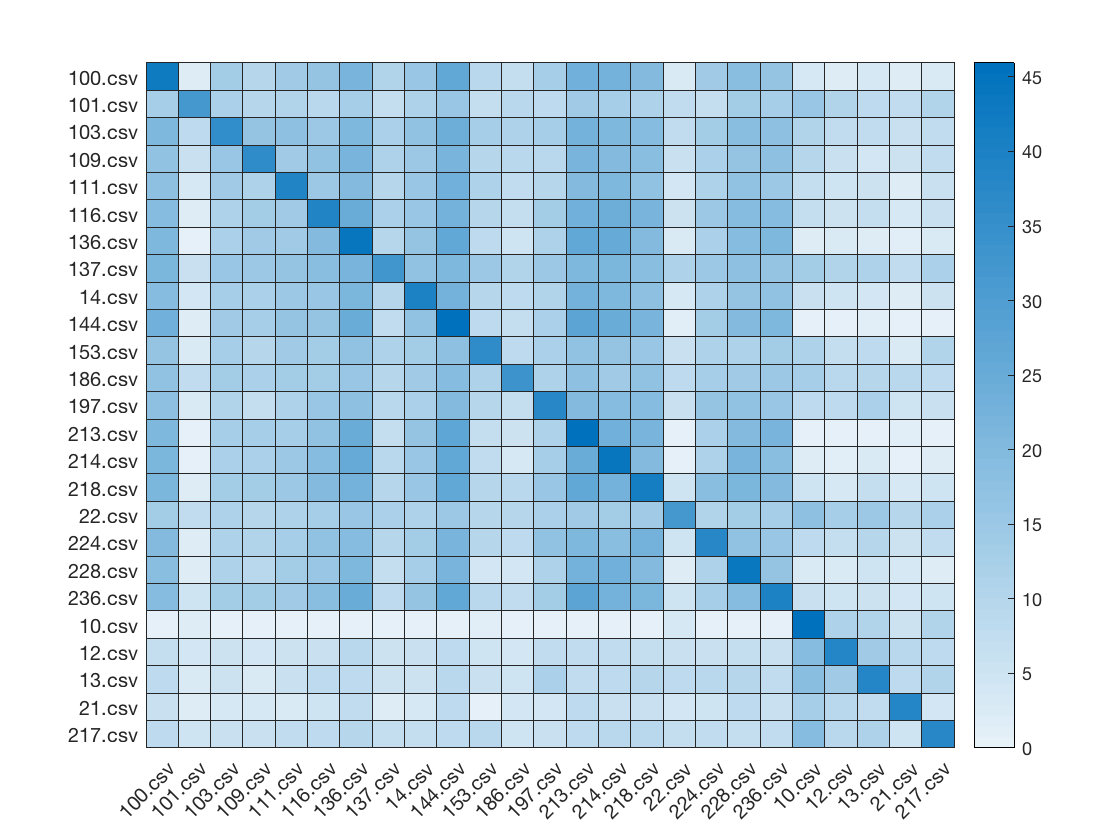

T = cluster(Z,'maxclust',2);
RT = [T, (1:length(T))'];
SRT = sortrows(RT);
SRT = SRT(:,2);
figure
heatmap(fileList(SRT),fileList(SRT),max(euclideanHost(SRT,SRT))-euclideanHost(SRT,SRT));

## Analysing it deeply

The hypothesis is that in the commercial properties industry there are 2 groups that diverge significantly. The first group might be the **Shopping malls, **whereas the second one might be **banks **and **business offices.**

**Let's confirm that**

commercial(:,:)

ans = 25×8 table
    SITE_ID         INDUSTRY                  SUB_INDUSTRY               SQ_FT        LAT        LNG           TIME_ZONE         TZ_OFFSET
    _______    ___________________    _____________________________    __________    ______    _______    ___________________    _________

     6         Commercial Property    Shopping Center/Shopping Mall    1.6153e+05    34.783     -106.9    America/Denver         -06:00   
     8         Commercial Property    Shopping Center/Shopping Mall    8.2397e+05     40.32    -76.405    America/New_York       -04:00   
     9         Commercial Property    Corporate Office                 1.6942e+05    40.947    -74.742    America/New_York       -04:00   
    10         

## Square feet vs. Power consumption

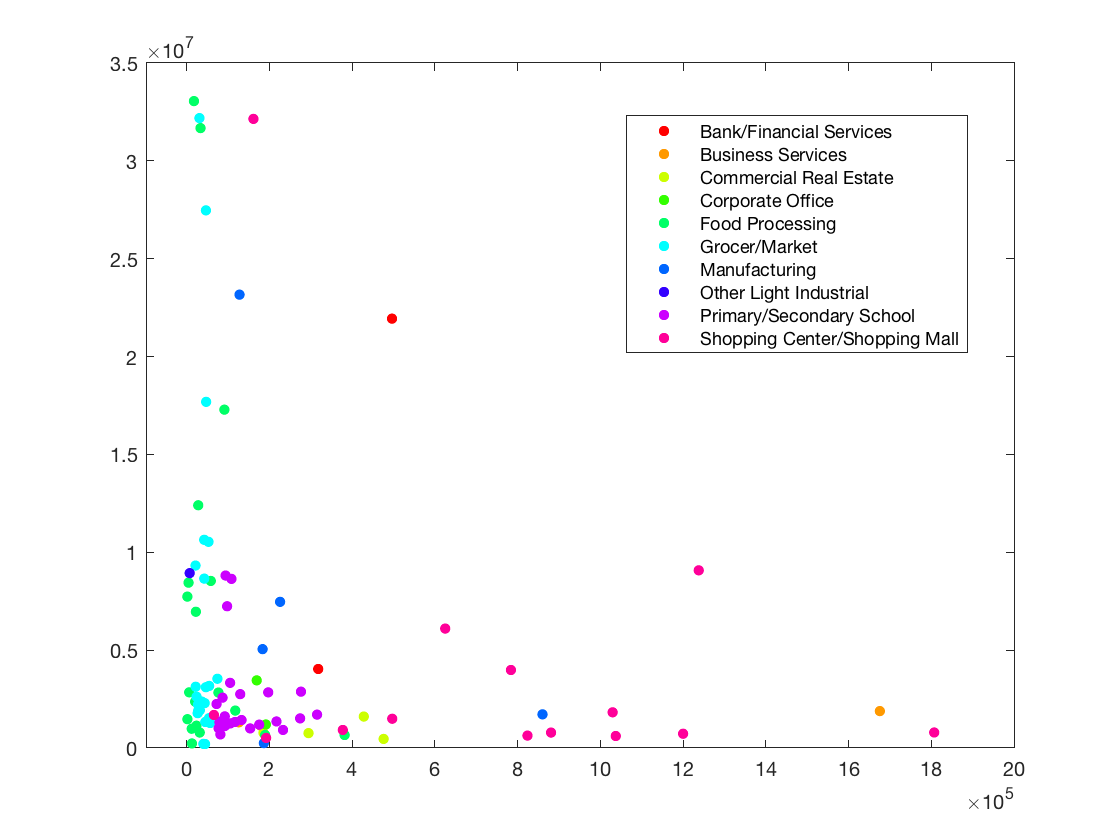

figure;
gscatter(allsites.SQ_FT, sum(data)',allsites.SUB_INDUSTRY)

## Stomp self join commercial properties

profile = zeros(9800,25,'single');
index = zeros(9800,25,'uint32');
for i = 1:25
    cdr = tsa.Array(commercialDataReduced(:,i));
    [p, in] = tsa.Matrix.stompSelfJoin(cdr, 201);
    profile(:,i) = p.getData();
    index(:,i) = in.getData();
end

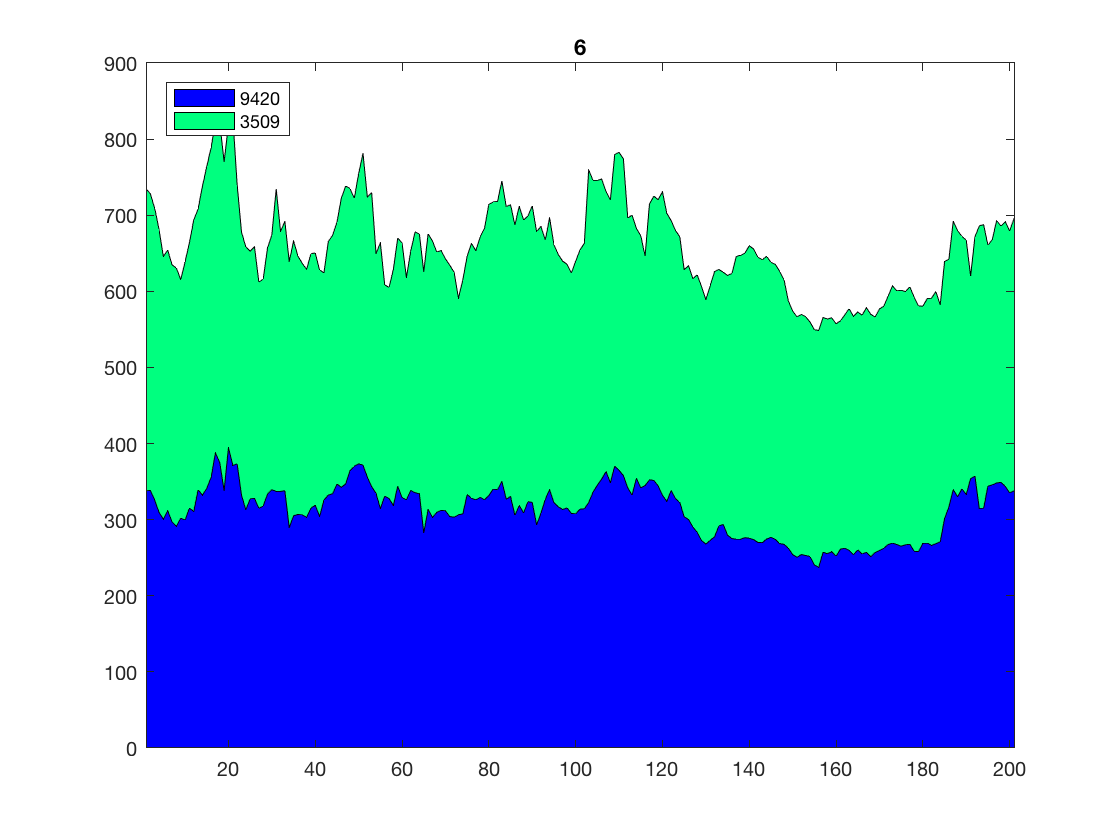

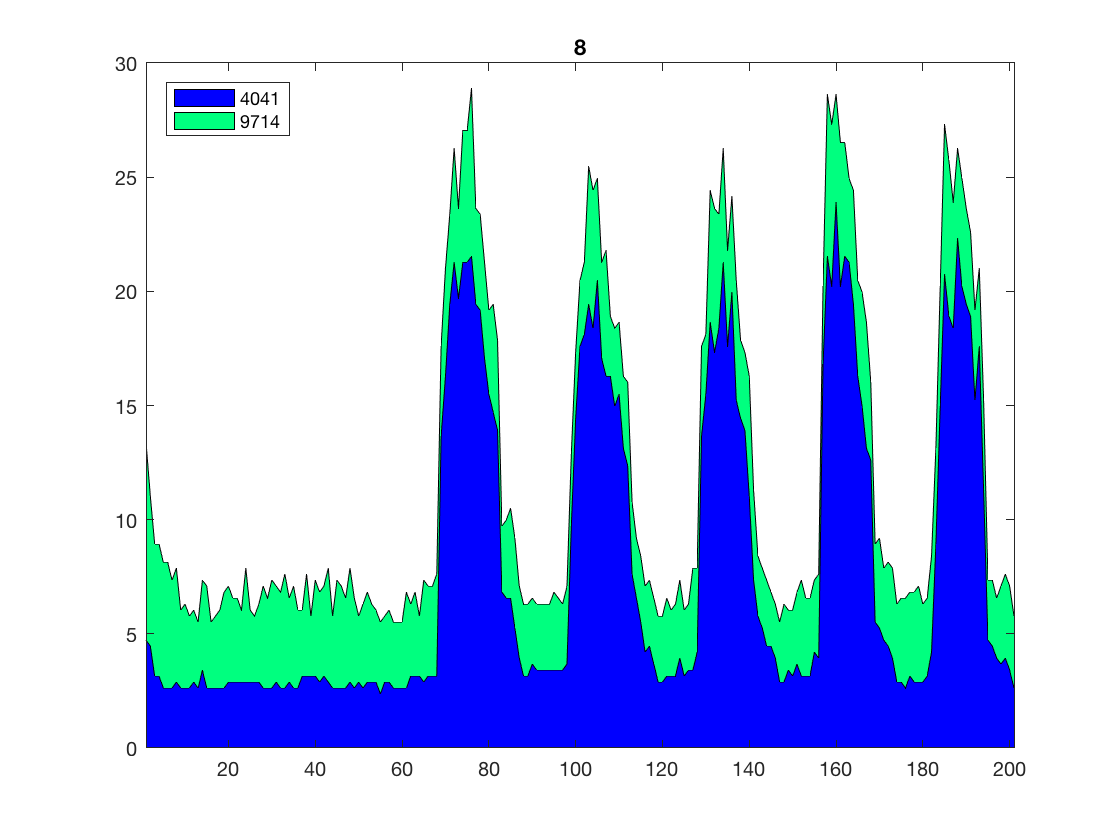

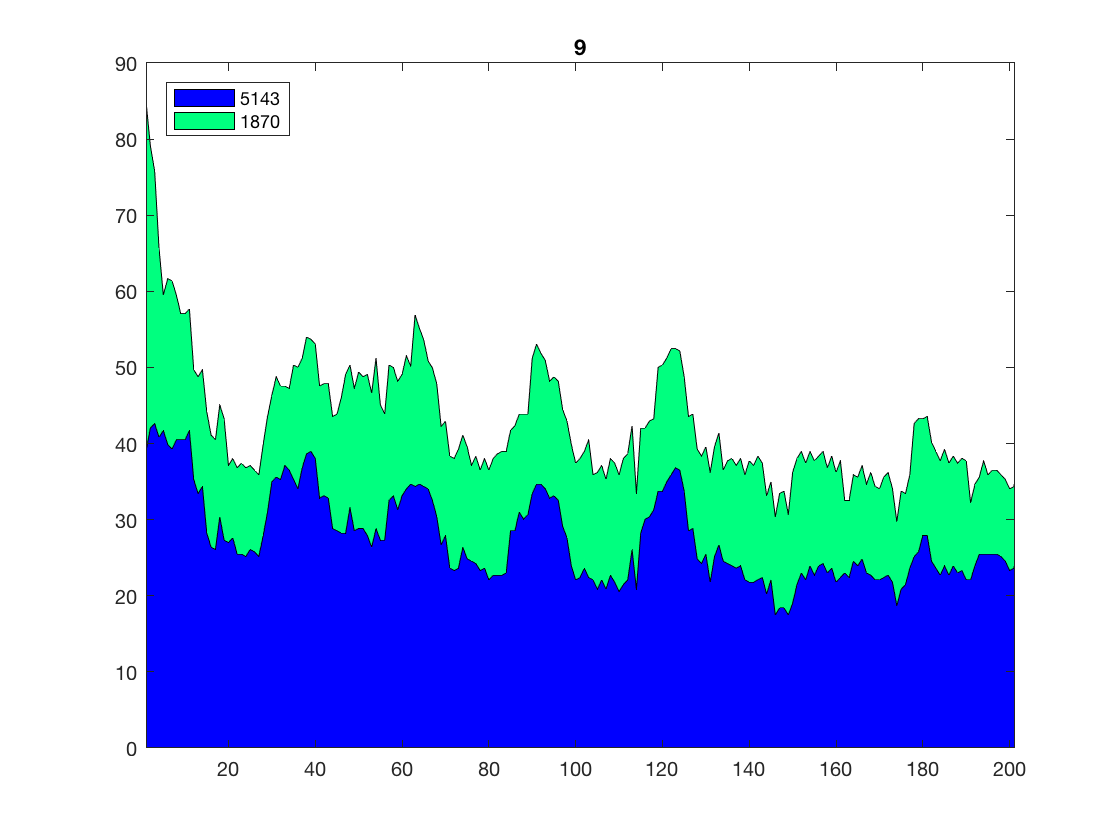

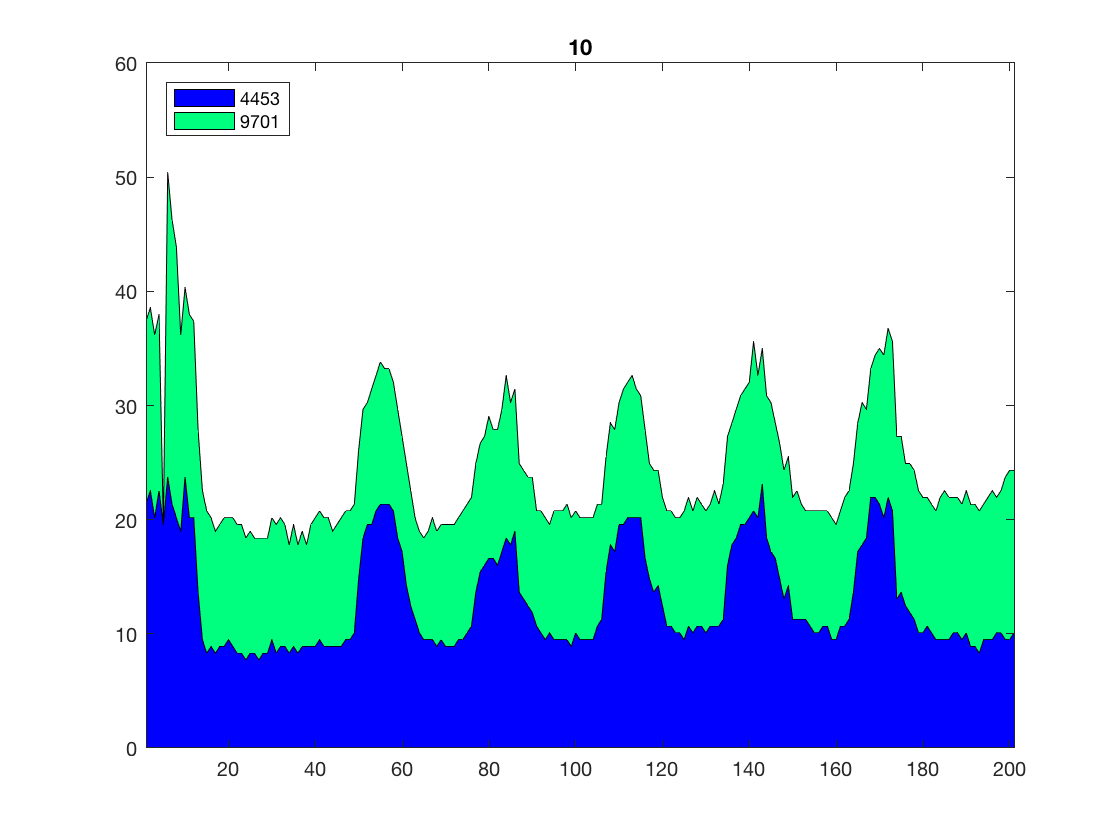

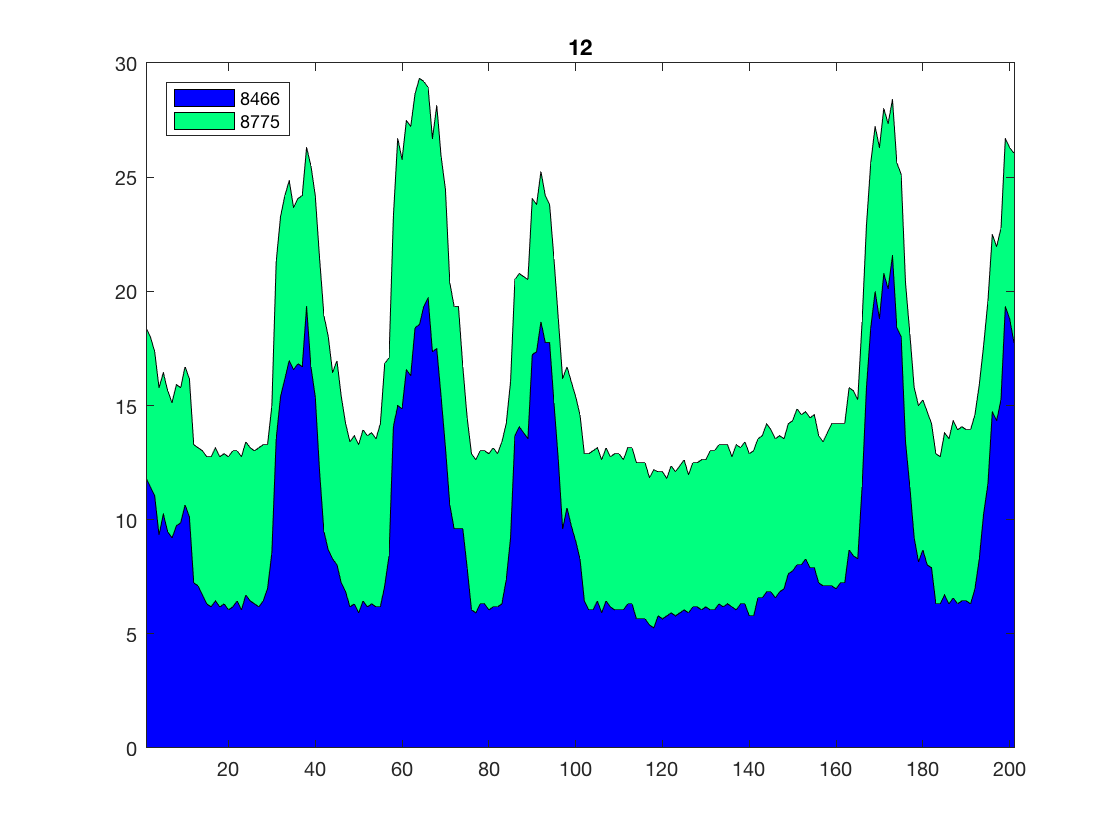

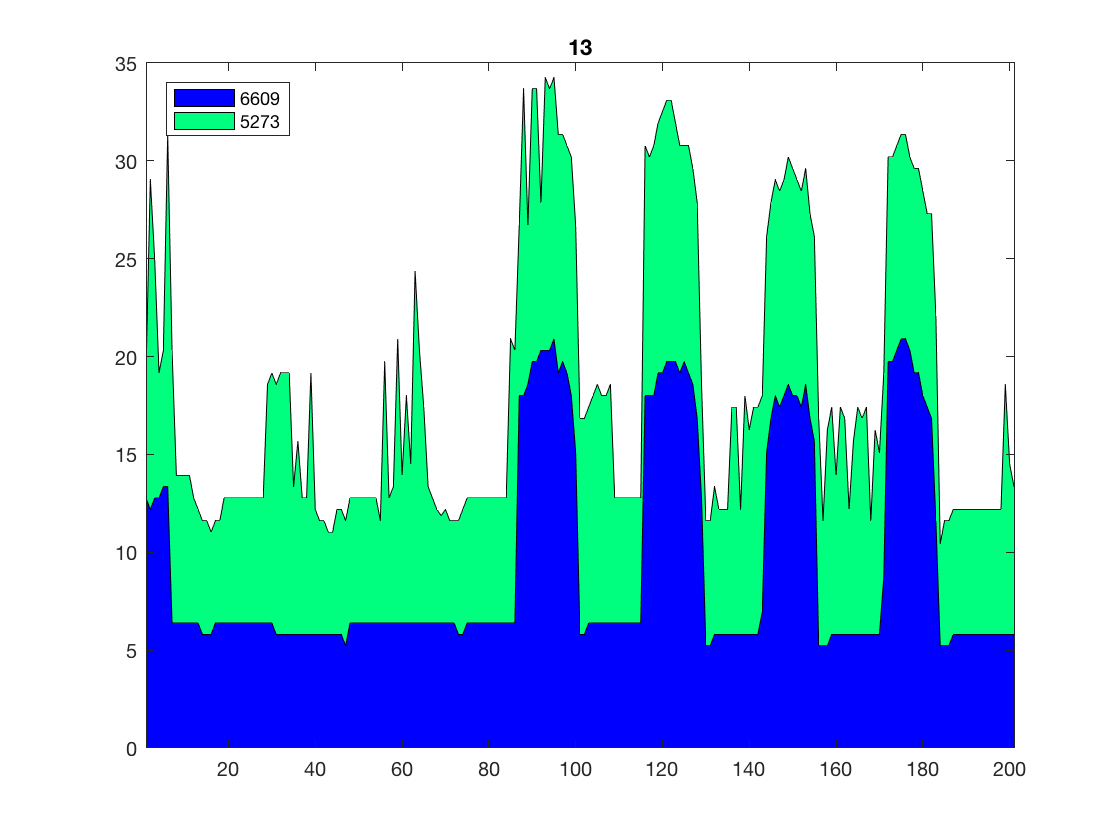

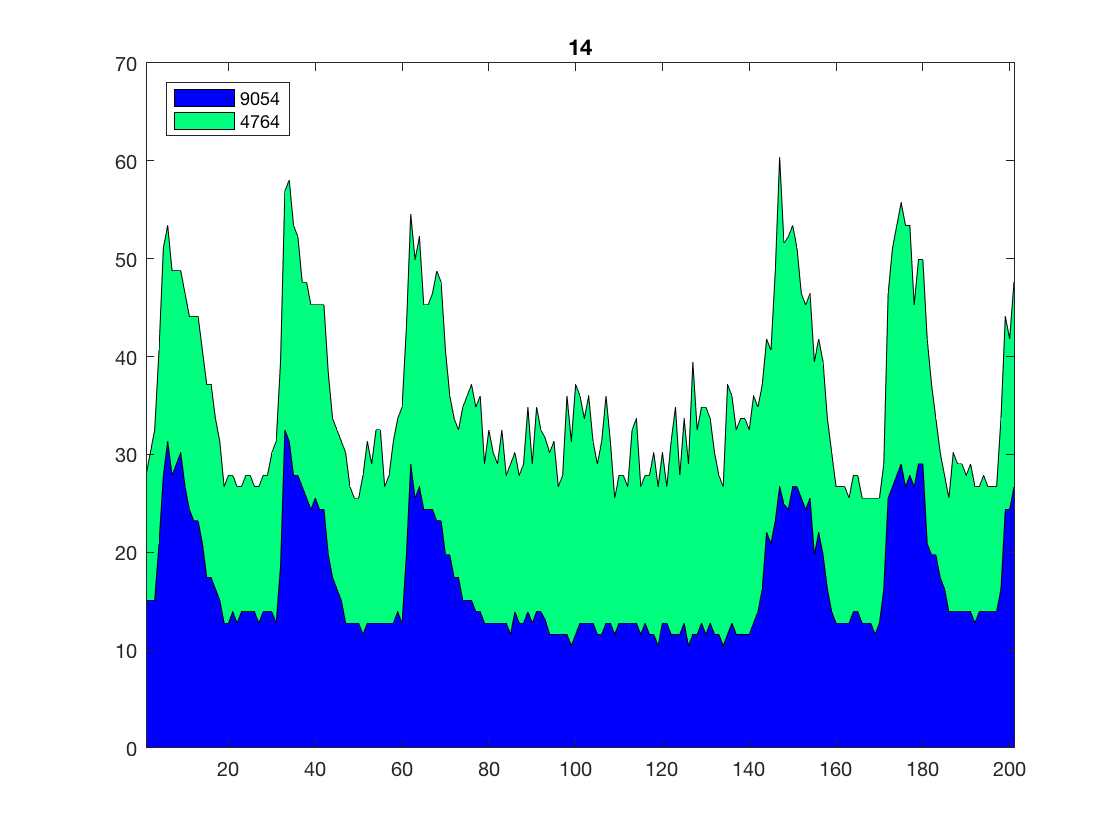

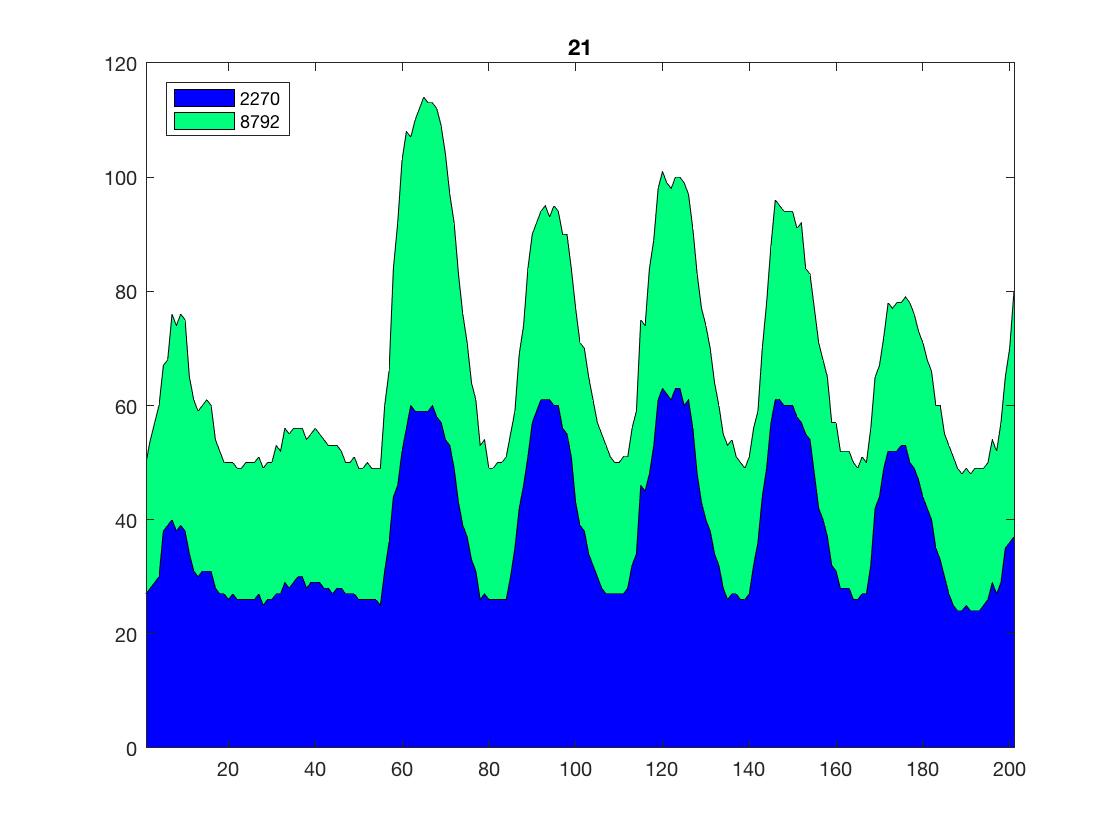

for i = 1:25
    p = tsa.Array(profile(:,i));
    in = tsa.Array(index(:,i));
    
    [md, mi, msi] = tsa.Matrix.findBestNMotifs(p, in, 10);
    miH = mi.getData();
    msiH = msi.getData();
%     for j = 1:1
%         figure;
%         area([commercialDataReduced(miH(j):miH(j)+201,i), commercialDataReduced(msiH(j):msiH(j)+201,i)],'FaceColor','flat');
%         colormap winter
%         legend([string(miH(j)), string(msiH(j))],'Location', 'NorthWest')
%         xlim([1 201])
%     end
    
    [dd, di, dsi] = tsa.Matrix.findBestNDiscords(p, in, 10);
    diH = di.getData();
    dsiH = dsi.getData();
    for j = 1:1
        figure;
        area([commercialDataReduced(diH(j):diH(j)+201,i), commercialDataReduced(dsiH(j):dsiH(j)+201,i)],'FaceColor','flat');
        colormap winter
        title(commercial.SITE_ID(i));
        legend([string(diH(j)), string(dsiH(j))],'Location', 'NorthWest')
        xlim([1 201])
    end
end